# Projeto4: 2DPCA Bidirecional

#### UFAM/PPGEE/Apredizado de Máquina 2021-1

Carlos Fonseca, Willian Guerreiro


clc
clear all;
close all;
load ORL_FaceDataSet;  % ATT Face Dataset com 40 indivíduos (classes) e 10 amostras de cada
A=double(ORL_FaceDataSet);

 
Num_Class = 40;
No_SampleClass = 10;
DIM = 10;    % Qtde de Autovetores (DIM: 1 a n)

%  Definição do Conjunto de Treinamento
%  ------------------------------------
No_TrainSamples = 7;
No_TestSamples  = 3;

[TrainData, TestData]    = Train_Test(A,No_SampleClass,No_TrainSamples,No_TestSamples);
[m,n,TotalTrainSamples]  = size(TrainData);
% m = 112
% n =  92
% TotalTrainSamples: 200

%  Definição do Conjunto de Testes
[m1,n1,TotalTestSamples] = size(TestData);
[TrainLabel,TestLabel]   = LebelSamples(Num_Class, No_TrainSamples, No_TestSamples);

% m1 = 112
% n1 =  92
% TotalTestSamples: 200


% Cálculo da Matriz de Covariancia (Projeção Horizontal)
% Gh = 1/n * SUM (Ai - Mean(A))'*(Ai - Mean(A)), i = 1:n
%-----------------------------------------------------------------------------
TrainMean = mean(TrainData,3); % Média do conjunto de treinamento na dimensão "z"
Gh=zeros([ n n]);

% TrainData é um conjunto de 200 imagens de tamanho 'mxn':
% m = 112
% n =  92

for i = 1:TotalTrainSamples
    Temp = TrainData(:,:,i) - TrainMean; % (Ai - Mean(A))
    Gh = Gh + Temp'*Temp;                % (Ai - Mean(A))'*(Ai - Mean(A))
end

Gh=Gh/TotalTrainSamples;                 % fator 1/N, N: 200
%Gh é n x n:  92 x 92 

% Cálculo da Matriz de Dispersão Vertical
% Gv = 1/n * SUM (Ai - Mean(A))*(Ai - Mean(A))', i = 1:n
%-----------------------------------------------------------------------------
TrainMean = mean(TrainData,3); % Média do conjunto de treinamento na dimensão "z"
Gv=zeros([ m m]);

for i = 1:TotalTrainSamples              % TotalTrainSamples : 200
    Temp = TrainData(:,:,i) - TrainMean; % (Ai - Mean(A)): m x n
    Gv = Gv + Temp*Temp';                % (Ai - Mean(A))'*(Ai - Mean(A)): (m x n) * (n x m): m x m
end

Gv=Gv/TotalTrainSamples;                 % fator 1/N
%Gv é m x m:  112 x 112 

%Redução de dimensionalidade com 2DLDA_BI

[U, V] = R_2DLDA_BI('ORL');

  Columns 1 through 11

    5.3805         0         0         0         0         0         0         0         0         0         0
         0    4.1469         0         0         0         0         0         0         0         0         0
         0         0    1.5894         0         0         0         0         0         0         0         0
         0         0         0    1.0313         0         0         0         0         0         0         0
         0         0         0         0    0.8817         0         0         0         0         0         0
         0         0         0         0         0    0.7046         0         0         0         0         0
         0         0         0         0         0         0    0.6721         0         0         0         0
         0         0         0         0         0         0         0    0.5188         0         0         0
         0         0         0         0         0         0         0         0    0.41

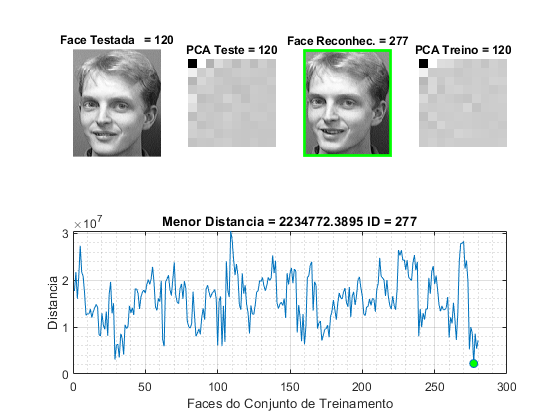


% Matriz de Projeção Horizontal U --> EigVect_H
% Maiores "q" Autovalores e Autovetores de Gh ("q" = DIM)
%----------------------------------------------
[EigVect1,EigVal1] = eig_decomp(Gh);
EigVect_H          = EigVect1(:,1:DIM);
% U = EigVect_H = n x q, n: 92 e q = DIM

% Matriz de Projeção Vertical V --> EigVect_V
% Maiores "q" Autovalores e Autovetores de Gh ("q" = DIM)
%----------------------------------------------
[EigVect1,EigVal1] = eig_decomp(Gv);
EigVect_V          = EigVect1(:,1:DIM); 
% V = EigVect_V = m x r, m: 112 e r = DIM


% Calculo das Imagens Projetadas do Cj. Treinamento
% Ap = V' * A * U (Ap: imagem projetada, A: imagem original)
% Ap = (r x m) * (m x n) * (n x q) = (r x m) * (m x q) = r x q
% ----------------------------------------------------------------------------------

for i = 1:TotalTrainSamples   
    Ytrain(:,:,i) = EigVect_V' * TrainData(:,:,i) * EigVect_H; % Ap = V' * A * U
    %Ytrain(:,:,i) = V' * TrainData(:,:,i) * U; % Ap = V' * A * U
end
% YTrain = Ap --> (r x q) = (DIM x DIM) = (10 x 10)


% Reconhecimento das Faces com o Conjunto de Teste
% 
%----------------------------------------------------
TestResult = zeros(TotalTestSamples,1);

for i=1:TotalTestSamples
    
    Distance = zeros(TotalTrainSamples,1);
    
    Ytest = EigVect_V' * TestData(:,:,i) * EigVect_H; 
    %Ytest = V' * TestData(:,:,i) * U; 
    % YTest = Ap = Imagems Projetadas com Dimensão Reduzida (10x10)
    % A projeção é feita a partir das matrized V e U obtidas das cj de treinamento
    % Ap também ser chamada de matriz de características (ou componentes) 
    % principais da imagem original
       
    for j = 1:TotalTrainSamples  % Cj Treinamento = 200
        for k=1:DIM
            % Calculo da mínima distância Horizontal (entre as colunas) das PCAs 
            % Distance(j) = Distance(j) + norm(Ytest(:,k)-Ytrain(:,k,j));              
            
            % Calcula da mínima distância Horizontal e Vertical das PCAs 
            d1 = Ytest(:,k)-Ytrain(:,k,j);
            d2 = Ytest(k,:)-Ytrain(k,:,j);            
            Distance(j) = Distance(j) + min(d1'*d1,d2*d2');
        end
    end
    % Medição das distâncias entre as Matrizes de Características 
    % Principais (Aps) dos conjuntos de Teste e Treinamento 
    % Para cada elemento do conjunto de Teste, 
    % Calcula-se a Distância entre 'Ytest' e os elementos do conjunto de Treinamento projetado 'Ytrain' (1 a 200) } 
    % A distância é soma das normas das diferencas entre cada coluna de Ytest - Ytrain
    
        
    [MINDIST ID]  = min(Distance);   % Obtem o valor e o índice do elemento que possui a menor distância
    TestResult(i) = TrainLabel(ID);  
    
    subplot(2,4,1);  imshow(TestData(:,:,i),[]);   title(['Face Testada   = ' num2str(i)]);
    subplot(2,4,2);  imshow(Ytest,[]);             title(['PCA Teste = ' num2str(i)]);
    subplot(2,4,3);  imshow(TrainData(:,:,ID),[]); title(['Face Reconhec. = ' num2str(ID)]);
    
    % Borda retangular ao redor da imagem reconhecida 
    % Verde -> Acerto
    % Vermelho -> Erro
    % --------------------------------------------------    
    if (TestResult(i) == TestLabel(i))
            rectangle('position',[1 1 n-1 m-1], 'edgecolor', [0 1 0], 'LineWidth', 2);
            cor = 'green';
            tempo = 0.01;
        else
            rectangle('position',[1 1 91 111], 'edgecolor', [1 0 0], 'LineWidth', 2);
            cor = 'red'; 
            tempo = 0.50;
    end
    subplot(2,4,4);  imshow(Ytrain(:,:,i),[]); title(['PCA Treino = ' num2str(i)]);
    subplot(2,4,[5 8]); plot(Distance,'-o','MarkerIndices',[ID ID],'MarkerFaceColor', cor,'MarkerSize',6);
    title(['Menor Distancia = ' num2str(MINDIST),' ID = ' num2str(ID)]);
    
    xlabel('Faces do Conjunto de Treinamento') 
    ylabel('Distancia') 
    
    grid on
    grid minor
     
    pause(tempo) %  Delay entre um reconhecimento e outro
    
   end


   Result = (TestResult == TestLabel);  
   % Result = '1' para os acertos (TestResult = TestLabel)

   CorrectRate = 100*(sum(Result/TotalTestSamples))

CorrectRate = 98.3333

   % Índice de Acerto 



    

